# SARS-CoV-19 transmission with time dependent infection rate

#### Overview

Matrix dimensions would not agree when I attempted to add in a vector that described the infection rate over time. Therefore, in this attempt I use an iterative method to fit the infection rate as a function  over time. The infection rate is done for every 2 days.  The fitting is done to minimize the mean squared error. 

With the current step size for beta and the number of days, the differential equations will need to be solved ~130,000 times. What will run time be? seems kinda dummy slow...

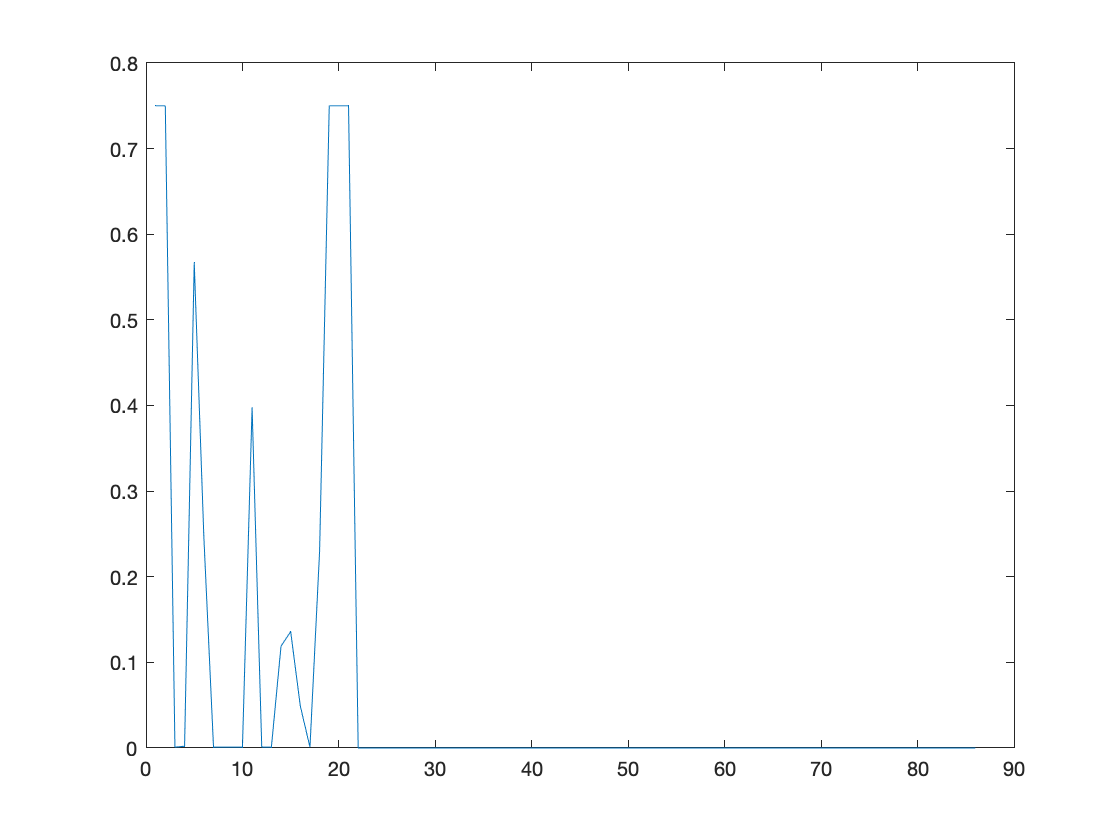

clearvars; clc;

% imports data from downloaded Johns Hopkins
M = csvread("US_covid_nums.csv");

US_confirmed = flip(M(1:173,1));
US_deaths = flip(M(1:173, 2));
US_recovered = flip(M(1:173, 3));

US_infected = US_confirmed-US_deaths-US_recovered;

[days_after_jan_22,~] = size(M);

% define several (currently static) parameters

N = 328.2e6;
eps = 38.4156/112.846;
fitted_beta = zeros(86,1);

% starts from January 22, where 1 person is confirmed infected,
% and we assume that 9 (?) people have been exposed.

y0 = [N-10,9,1,0,0,0,0,0,0,0,0,0,0,0];

% range of beta values
% if a certain num are by the min or max, be sure to expand the range

lower_b = .001;
upper_b = .75;
b_step = .001;

% iterate through days and beta vals to find lowest MSE
tspan = 0:2;
for time_chunk = 1:2:171
    %least_squares_vals = ones((upper_b-lower_b)/b_step,1);
    best_MSE = 10000;
    for test_beta = lower_b:b_step:upper_b
        [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,test_beta),tspan,y0);
        actual_vals = US_infected((time_chunk+1):(time_chunk+2),1);
        predicted_vals = y(2:3, 3:4) + y(2:3, 9:10);
        MSE = sum(sum((predicted_vals-actual_vals).^2))/4;
        
        if (MSE < best_MSE)
            fitted_beta((time_chunk+1)/2,1) = test_beta;
            best_MSE = MSE;
        end
        
    end
    
    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,fitted_beta((time_chunk+1)/2,1)),tspan,y0);
    y0 = y(3,:);
end

plot(fitted_beta);

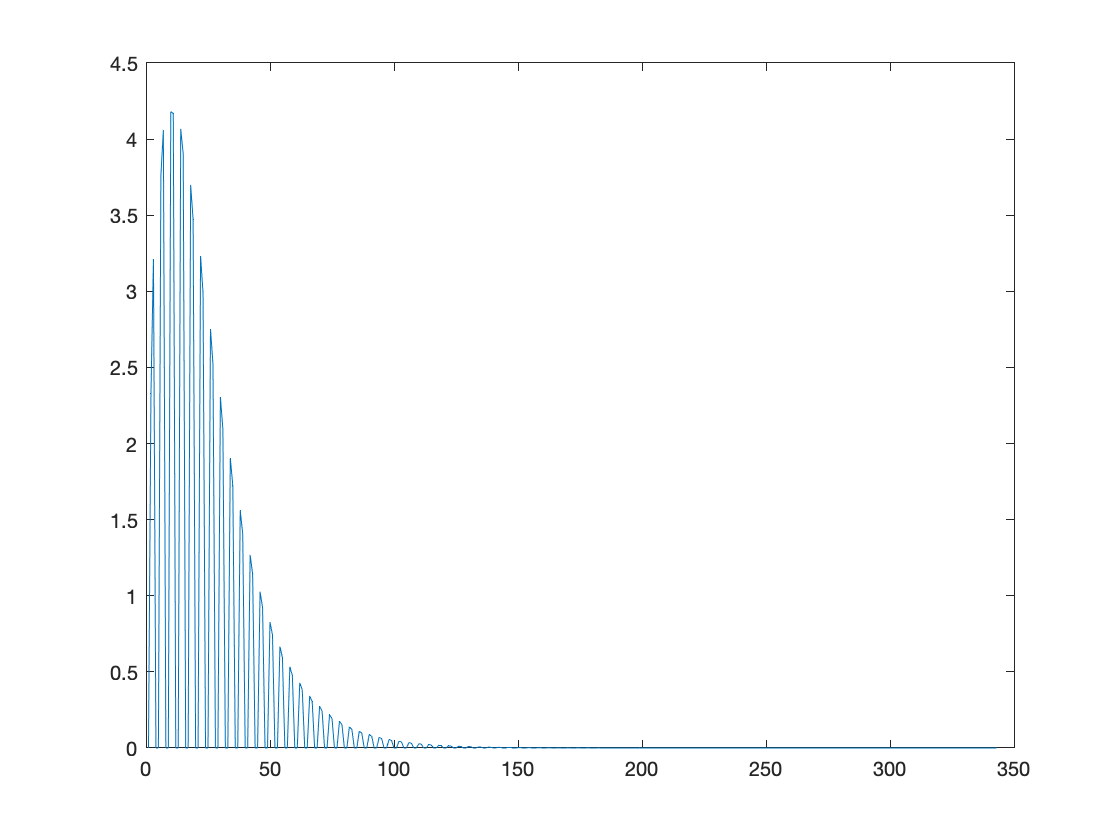


beta_test = .01*ones(173,1);
y0 = [N-10,9,1,0,0,0,0,0,0,0,0,0,0,0];
modeled_infec = zeros(173,1);

for time_chunk = 1:2:171
    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,.01),tspan,y0);
    modeled_infec(time_chunk*2:(time_chunk*2+1),1) = y(2:3, 3) + y(2:3, 4) + y(2:3, 9) + y(2:3, 10);
    y0 = y(3,:);
end

figure;
plot(modeled_infec);